## Preprocessing and Feature Extraction

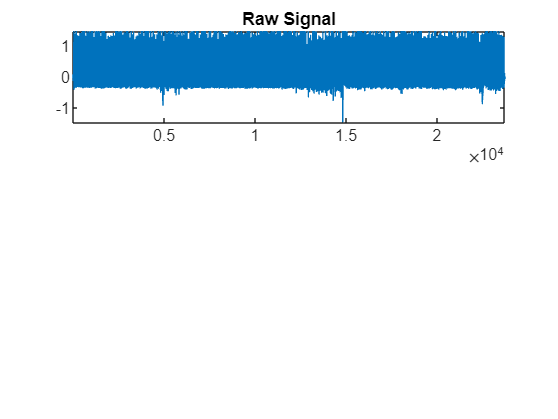

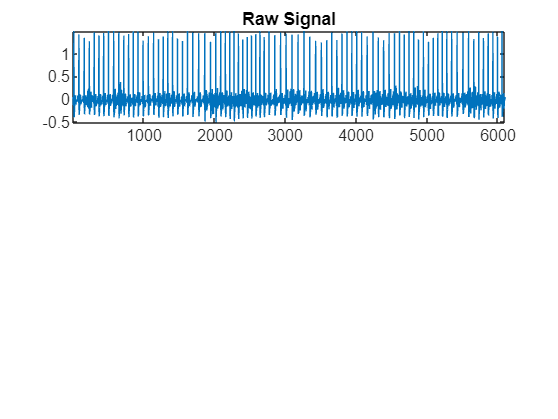

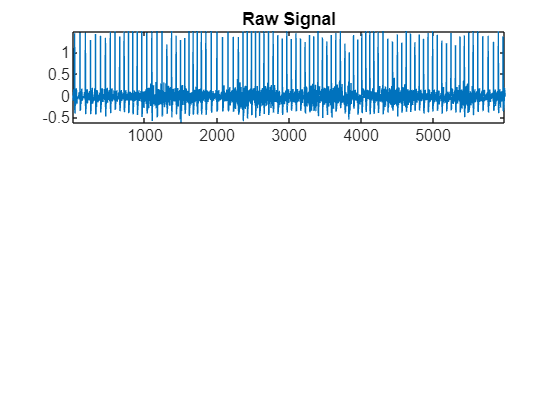

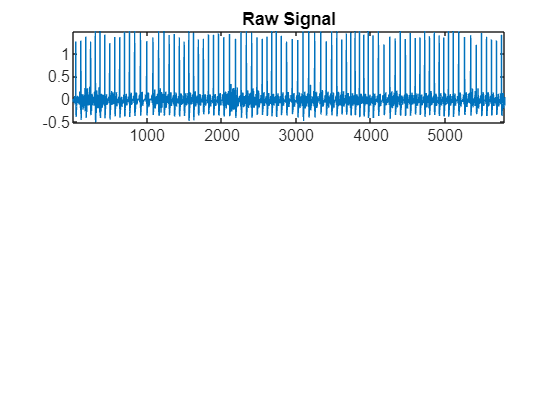

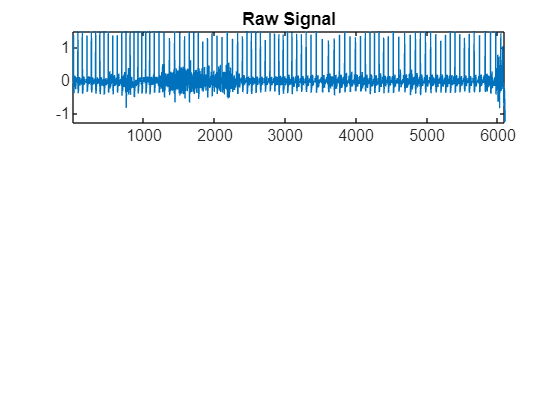

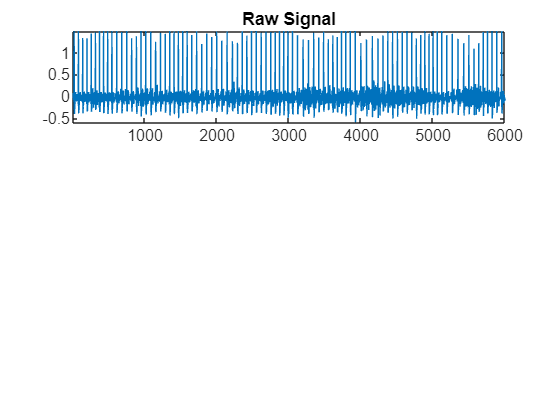

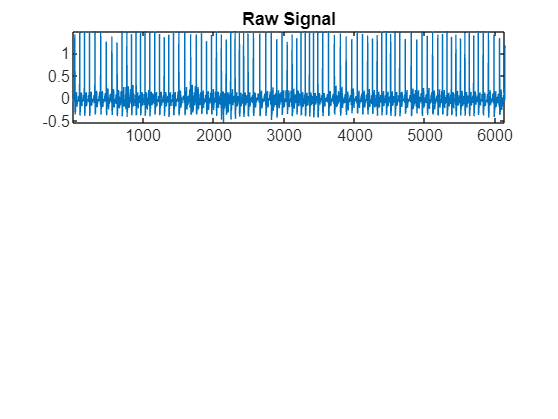

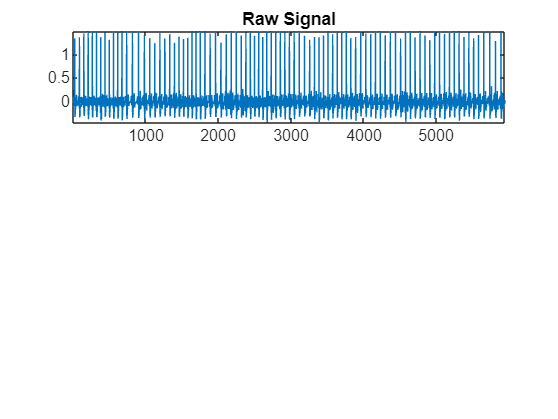

Baris 1 telah ditulis ke Excel.
Baris 2 telah ditulis ke Excel.
Baris 3 telah ditulis ke Excel.
Baris 4 telah ditulis ke Excel.
Baris 5 telah ditulis ke Excel.
Baris 6 telah ditulis ke Excel.
Baris 7 telah ditulis ke Excel.
Baris 8 telah ditulis ke Excel.
Baris 9 telah ditulis ke Excel.
Baris 10 telah ditulis ke Excel.
Baris 11 telah ditulis ke Excel.
Baris 12 telah ditulis ke Excel.
Baris 13 telah ditulis ke Excel.
Baris 14 telah ditulis ke Excel.
Baris 15 telah ditulis ke Excel.
Baris 16 telah ditulis ke Excel.
Baris 17 telah ditulis ke Excel.


Semua baris telah ditulis ke file Excel.


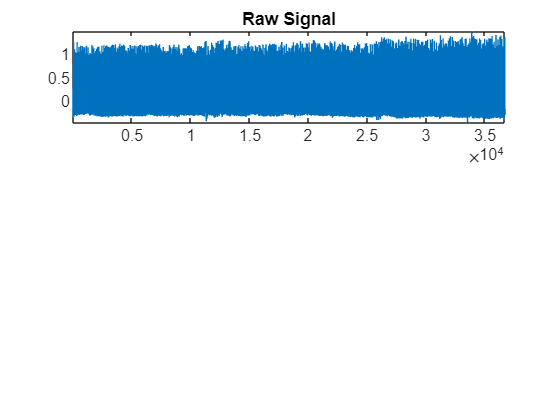

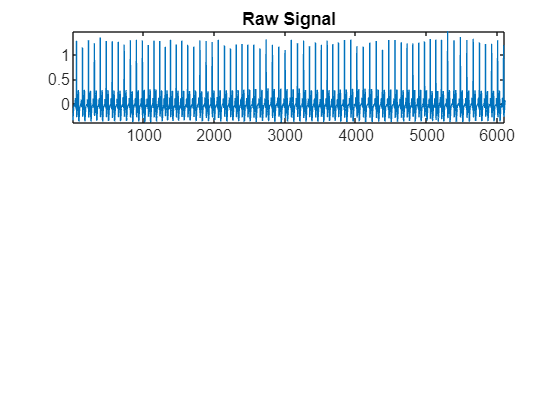

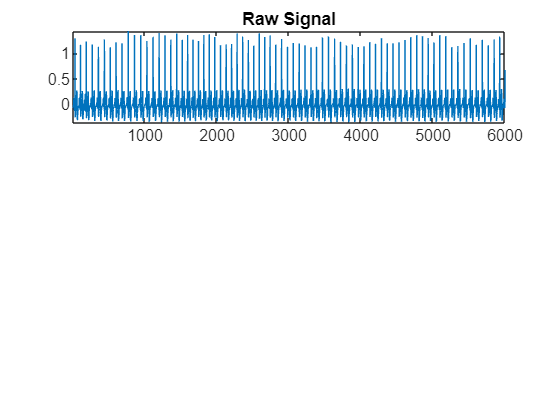

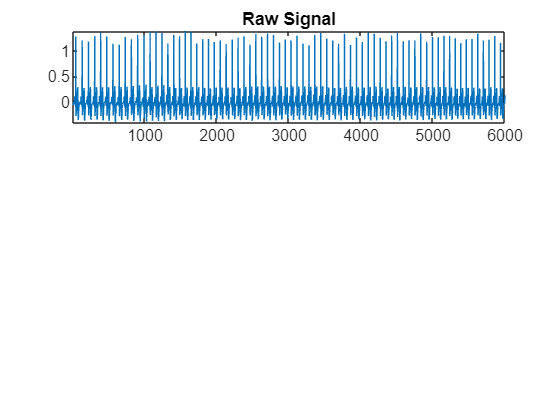

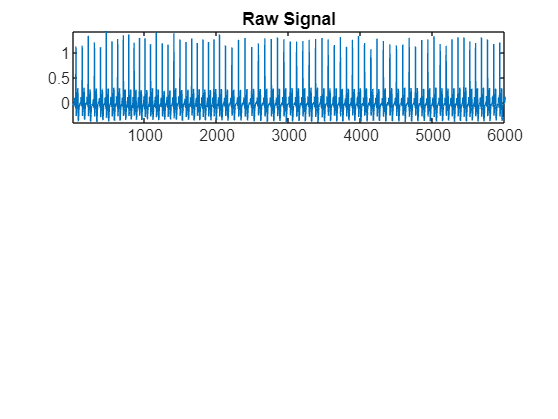

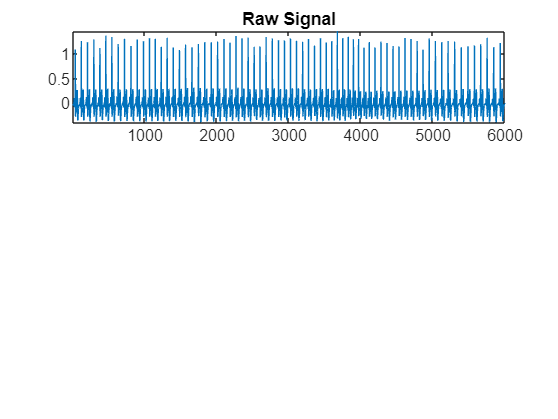

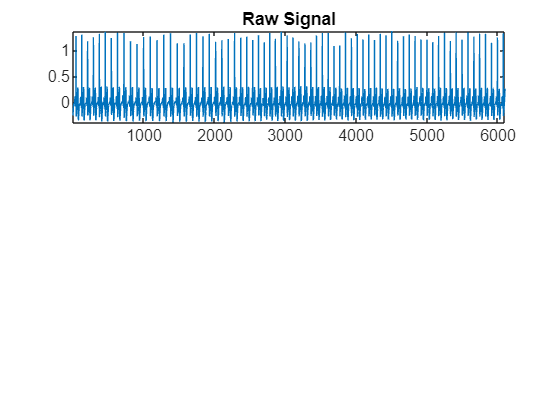

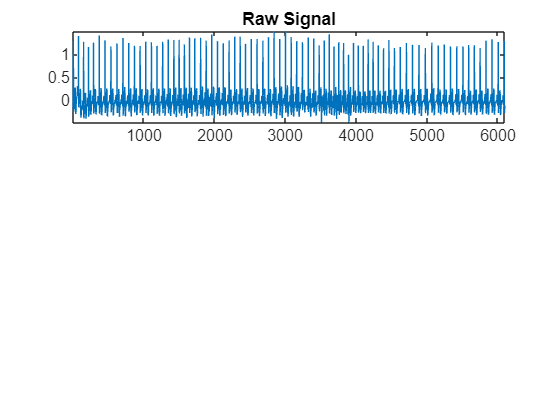

Baris 1 telah ditulis ke Excel.
Baris 2 telah ditulis ke Excel.
Baris 3 telah ditulis ke Excel.
Baris 4 telah ditulis ke Excel.
Baris 5 telah ditulis ke Excel.
Baris 6 telah ditulis ke Excel.
Baris 7 telah ditulis ke Excel.
Baris 8 telah ditulis ke Excel.
Baris 9 telah ditulis ke Excel.
Baris 10 telah ditulis ke Excel.
Baris 11 telah ditulis ke Excel.
Baris 12 telah ditulis ke Excel.
Baris 13 telah ditulis ke Excel.
Baris 14 telah ditulis ke Excel.
Baris 15 telah ditulis ke Excel.
Baris 16 telah ditulis ke Excel.
Baris 17 telah ditulis ke Excel.


Semua baris telah ditulis ke file Excel.


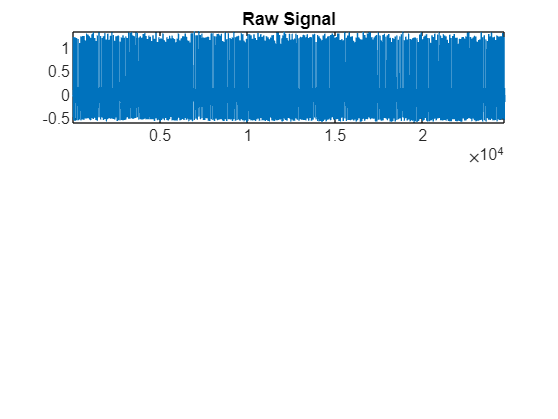

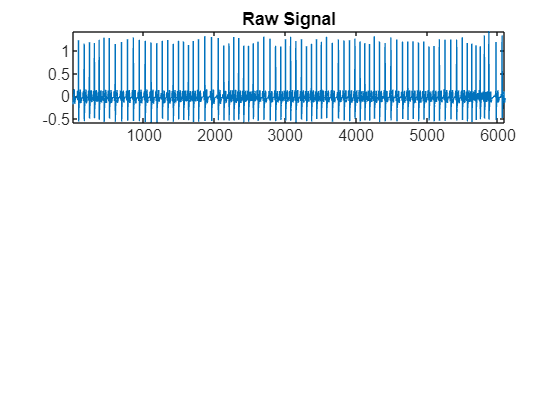

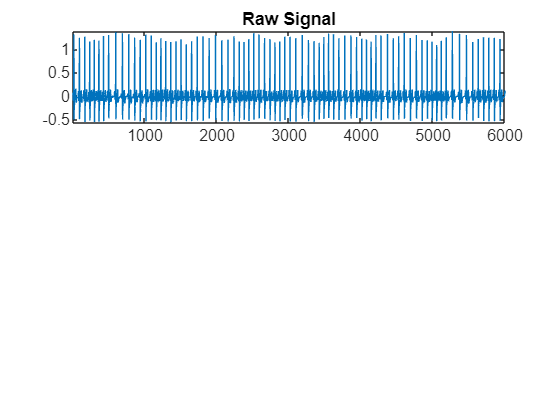

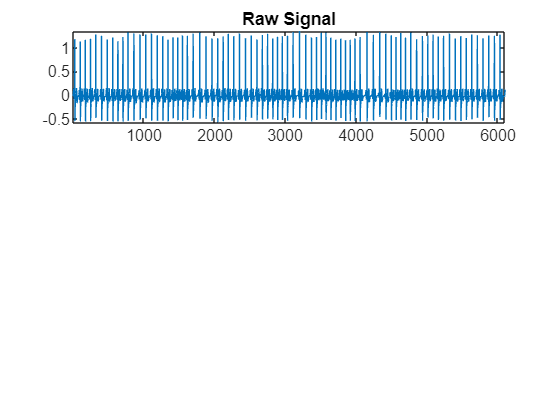

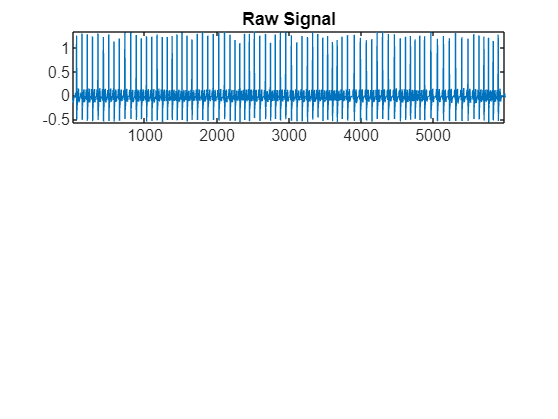

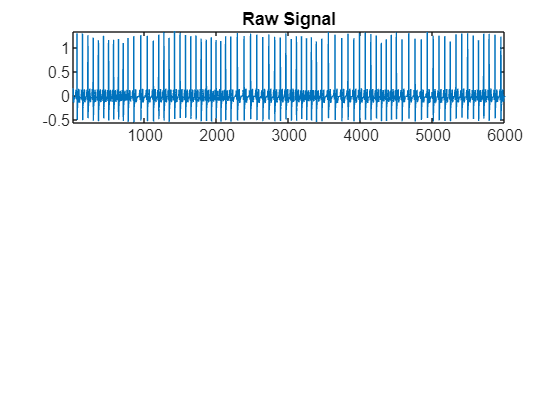

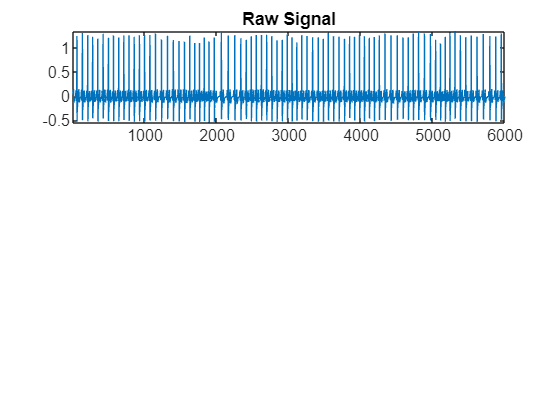

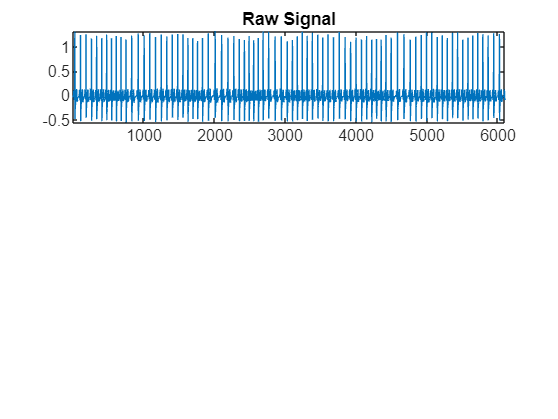

Baris 1 telah ditulis ke Excel.
Baris 2 telah ditulis ke Excel.
Baris 3 telah ditulis ke Excel.
Baris 4 telah ditulis ke Excel.
Baris 5 telah ditulis ke Excel.
Baris 6 telah ditulis ke Excel.
Baris 7 telah ditulis ke Excel.
Baris 8 telah ditulis ke Excel.
Baris 9 telah ditulis ke Excel.
Baris 10 telah ditulis ke Excel.
Baris 11 telah ditulis ke Excel.
Baris 12 telah ditulis ke Excel.
Baris 13 telah ditulis ke Excel.
Baris 14 telah ditulis ke Excel.
Baris 15 telah ditulis ke Excel.
Baris 16 telah ditulis ke Excel.
Baris 17 telah ditulis ke Excel.


Semua baris telah ditulis ke file Excel.


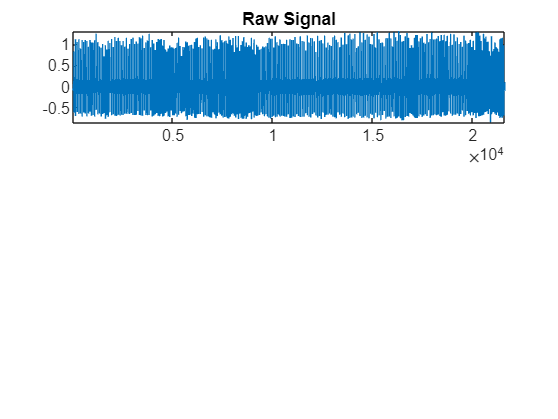

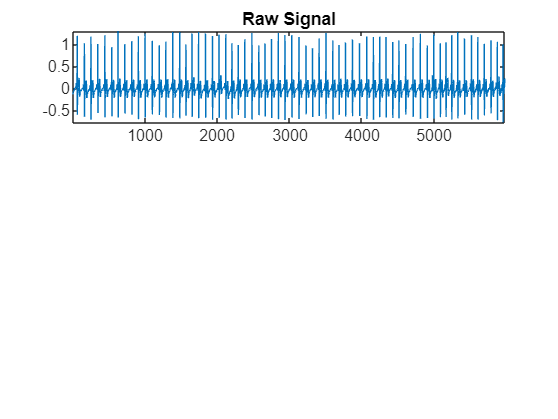

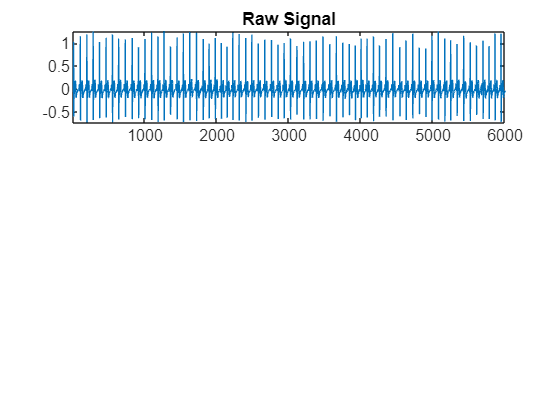

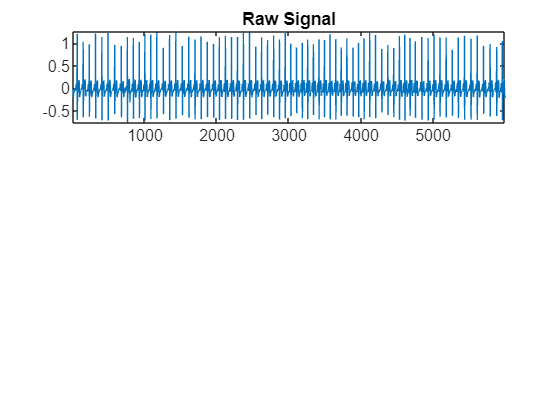

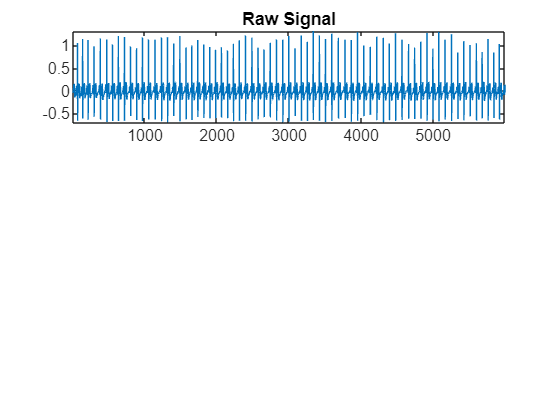

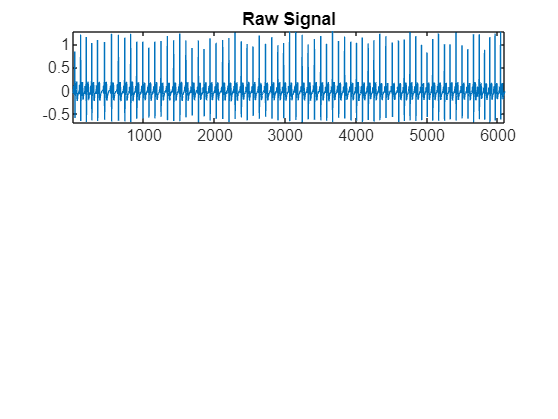

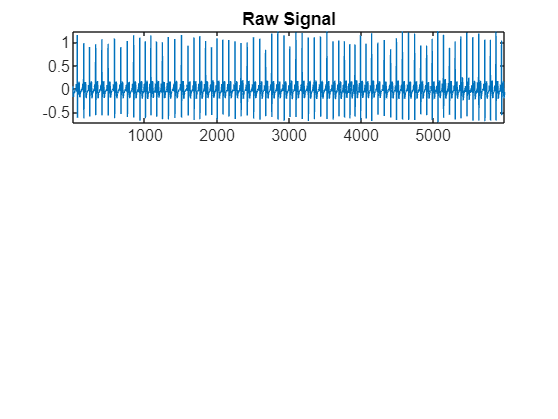

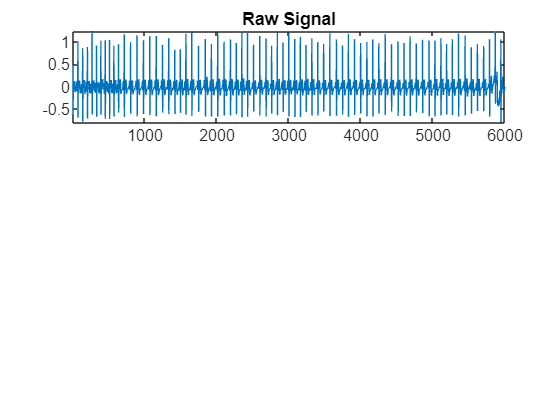

Baris 1 telah ditulis ke Excel.
Baris 2 telah ditulis ke Excel.
Baris 3 telah ditulis ke Excel.
Baris 4 telah ditulis ke Excel.
Baris 5 telah ditulis ke Excel.
Baris 6 telah ditulis ke Excel.
Baris 7 telah ditulis ke Excel.
Baris 8 telah ditulis ke Excel.
Baris 9 telah ditulis ke Excel.
Baris 10 telah ditulis ke Excel.
Baris 11 telah ditulis ke Excel.
Baris 12 telah ditulis ke Excel.
Baris 13 telah ditulis ke Excel.
Baris 14 telah ditulis ke Excel.
Baris 15 telah ditulis ke Excel.
Baris 16 telah ditulis ke Excel.
Baris 17 telah ditulis ke Excel.


Semua baris telah ditulis ke file Excel.


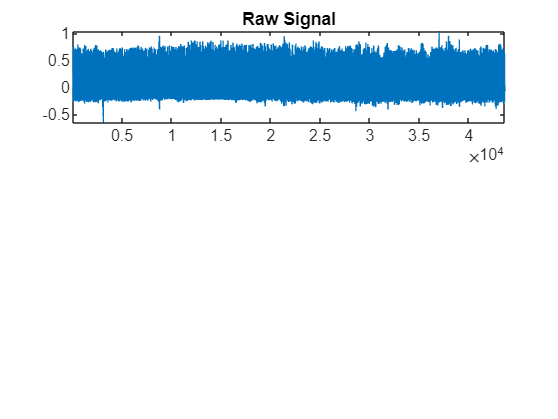

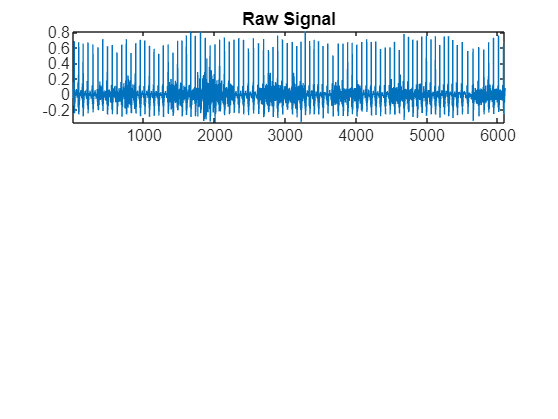

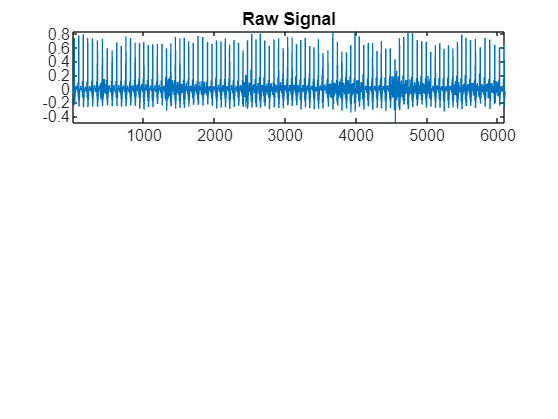

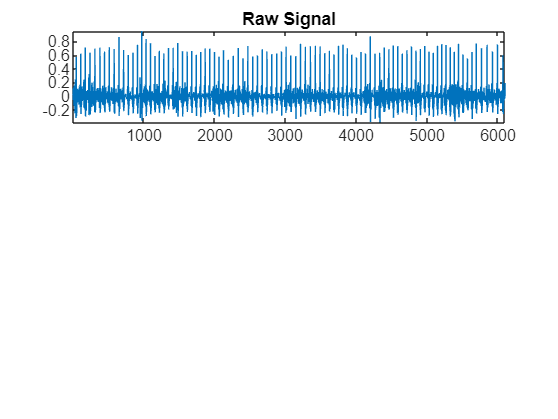

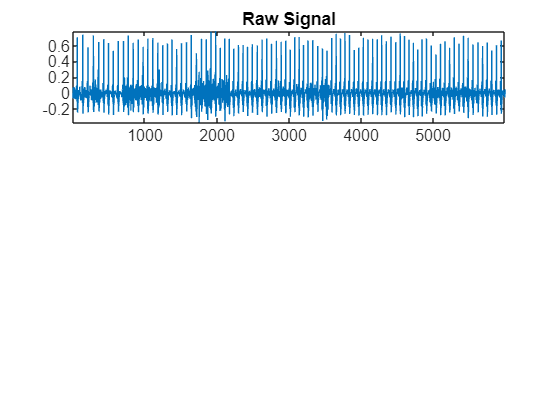

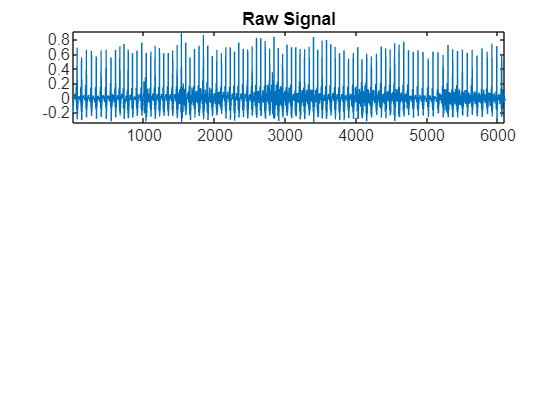

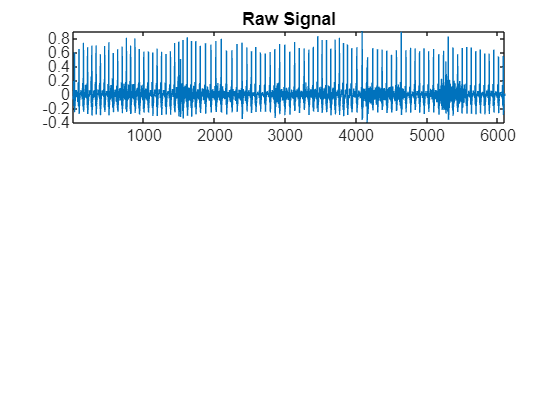

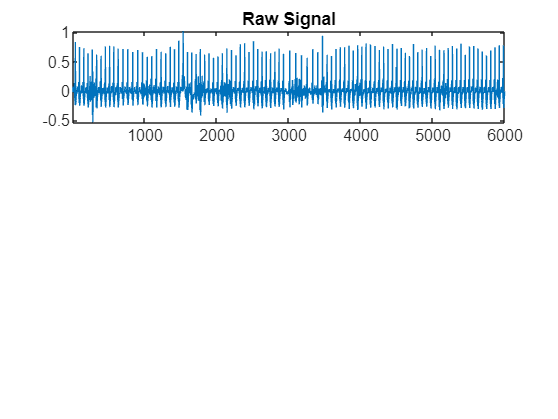

Baris 1 telah ditulis ke Excel.
Baris 2 telah ditulis ke Excel.
Baris 3 telah ditulis ke Excel.
Baris 4 telah ditulis ke Excel.
Baris 5 telah ditulis ke Excel.
Baris 6 telah ditulis ke Excel.
Baris 7 telah ditulis ke Excel.
Baris 8 telah ditulis ke Excel.
Baris 9 telah ditulis ke Excel.
Baris 10 telah ditulis ke Excel.
Baris 11 telah ditulis ke Excel.
Baris 12 telah ditulis ke Excel.
Baris 13 telah ditulis ke Excel.
Baris 14 telah ditulis ke Excel.
Baris 15 telah ditulis ke Excel.
Baris 16 telah ditulis ke Excel.
Baris 17 telah ditulis ke Excel.


Semua baris telah ditulis ke file Excel.


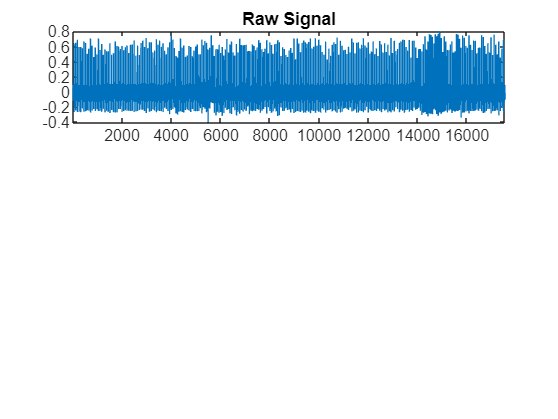

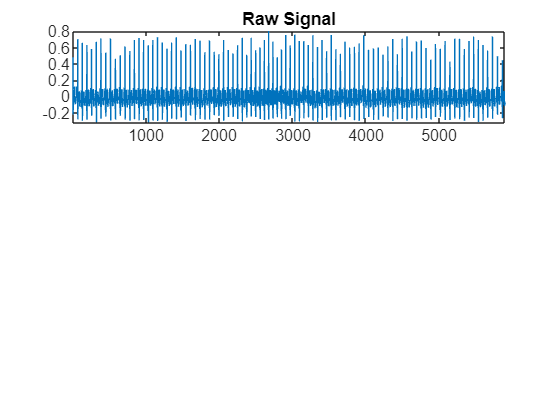

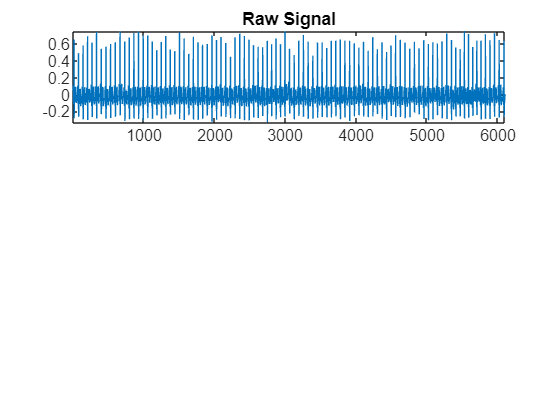

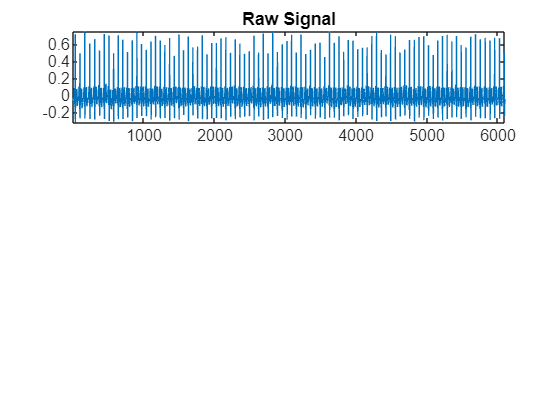

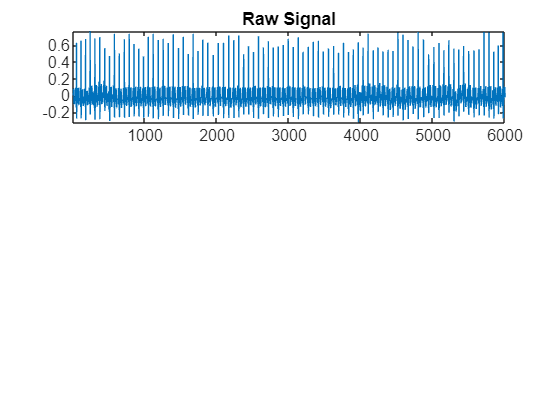

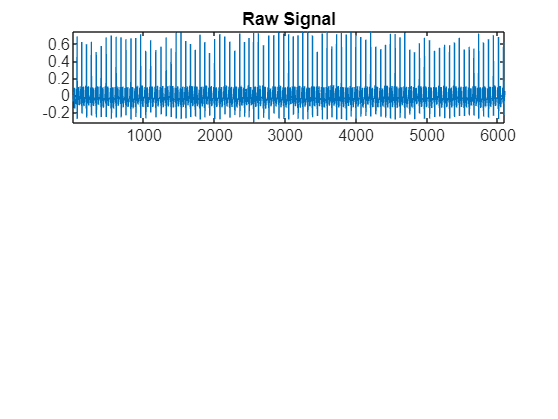

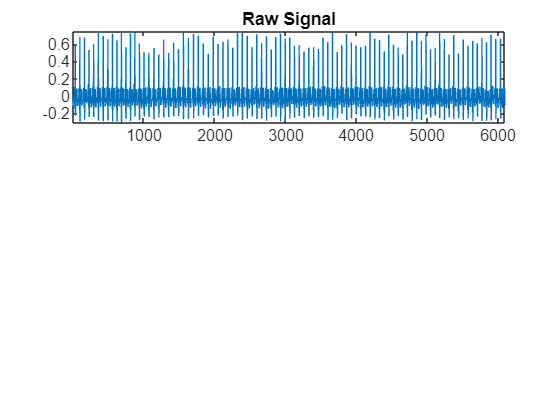

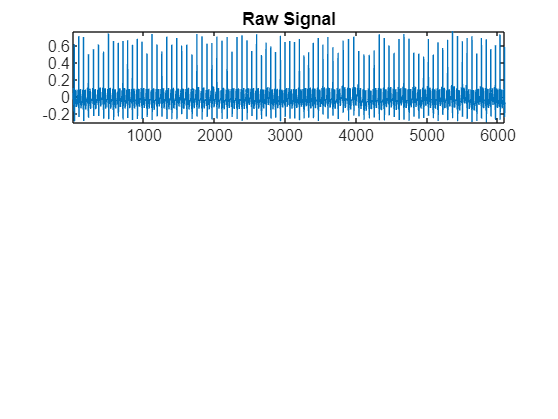

Baris 1 telah ditulis ke Excel.
Baris 2 telah ditulis ke Excel.
Baris 3 telah ditulis ke Excel.
Baris 4 telah ditulis ke Excel.
Baris 5 telah ditulis ke Excel.
Baris 6 telah ditulis ke Excel.
Baris 7 telah ditulis ke Excel.
Baris 8 telah ditulis ke Excel.
Baris 9 telah ditulis ke Excel.
Baris 10 telah ditulis ke Excel.
Baris 11 telah ditulis ke Excel.
Baris 12 telah ditulis ke Excel.
Baris 13 telah ditulis ke Excel.
Baris 14 telah ditulis ke Excel.
Baris 15 telah ditulis ke Excel.
Baris 16 telah ditulis ke Excel.
Baris 17 telah ditulis ke Excel.


Semua baris telah ditulis ke file Excel.


fname1 ='BitalinoECG.txt';
fname2 = 'Triggers.txt';
fld ='Dataset';
count = 0;

% Nama file Excel yang akan dibuat
result_file = 'hasil_ekstraksi.xlsx';

% Inisialisasi header (nama kolom)
headers = {'Subjek', 'Clip', 'Label', 'HR', 'RMSSD', 'SDNN', 'SDSD', 'PNN50', 'pNN20', 'NN20', 'pLF', 'pHF', 'LFHratio', 'VLF', 'LF', 'HF'};

% Tulis header ke file Excel (menulis di sel A1:J1)
writecell(headers, result_file, 'Sheet', 1, 'Range', 'A1');

% Tentukan jumlah baris data yang akan diproses
numRows = 10000000;  % Sesuaikan dengan kebutuhan Anda

for num = 1:10
    %Import file ECG dan Trigger
    ECGfilename = ['C:\Users\kayyi\Music\Preprocessing Dataset\Dataset\','VP',num2str(num),'\',fname1];
    if exist (ECGfilename, 'file') == 0
        %file does not exist
        continue;
    end

    Triggerfilename = ['C:\Users\kayyi\Music\Preprocessing Dataset\Dataset\','VP',num2str(num),'\',fname2];

    trig = importTrigger(Triggerfilename);
    ecg = importECG(ECGfilename);

    %Split Data
    row_ecg = size(ecg,1);
    col_ecg = size(ecg,2);
    row_trig = size(trig,1);
    col_trig = size(trig,2);
    
    baseline = zeros(1,1);
    demo = zeros(1,1);
    clip1 = zeros(1,1);
    clip2 = zeros(1,1);
    clip3 = zeros(1,1);
    clip4 = zeros(1,1);
    clip5 = zeros(1,1);
    clip6 = zeros(1,1);
    clip7 = zeros(1,1);
    clip8 = zeros(1,1);
    clip9 = zeros(1,1);
    clip10 = zeros(1,1);
    clip11 = zeros(1,1);
    clip12 = zeros(1,1);
    clip13 = zeros(1,1);
    clip14 = zeros(1,1);
    clip15 = zeros(1,1);
    clip16 = zeros(1,1);
    rest = zeros(1,1);
    
    %Baseline
    for i=1:row_ecg
        if ecg(i,2) < trig(1,1)
            baseline(i,1) = ecg(i,1);
    
        end
    end
    
    
    %Clip-Demo
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(1,1)) && (ecg(i,2) < trig(1,2))
            demo(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip1
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(2,1)) && (ecg(i,2) < trig(2,2))
            clip1(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip2
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(3,1)) && (ecg(i,2) < trig(3,2))
            clip2(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip3
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(4,1)) && (ecg(i,2) < trig(4,2))
            clip3(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip4
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(5,1)) && (ecg(i,2) < trig(5,2))
            clip4(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip5
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(6,1)) && (ecg(i,2) < trig(6,2))
            clip5(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip6
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(7,1)) && (ecg(i,2) < trig(7,2))
            clip6(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip7
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(8,1)) && (ecg(i,2) < trig(8,2))
            clip7(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip8
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(9,1)) && (ecg(i,2) < trig(9,2))
            clip8(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip9
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(10,1)) && (ecg(i,2) < trig(10,2))
            clip9(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip10
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(11,1)) && (ecg(i,2) < trig(11,2))
            clip10(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip11
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(12,1)) && (ecg(i,2) < trig(12,2))
            clip11(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip12
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(12,1)) && (ecg(i,2) < trig(12,2))
            clip12(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip13
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(14,1)) && (ecg(i,2) < trig(14,2))
            clip13(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip14
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(15,1)) && (ecg(i,2) < trig(15,2))
            clip14(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip15
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(16,1)) && (ecg(i,2) < trig(16,2))
            clip15(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Clip16
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(17,1)) && (ecg(i,2) < trig(17,2))
            clip16(j,1) = ecg(i,1);
            j=j+1;
        end
    end
    
    %Rest
    j=1;
    for i=1:row_ecg
        if (ecg(i,2) >= trig(18,1)) && (ecg(i,2) < trig(row_trig,2))
            rest(j,1) = ecg(i,1);
            j=j+1;
        end
    end

    % Simpan semua matriks dalam cell array
    all_clip = {baseline, clip1, clip2, clip3, clip4, clip5, clip6, clip7, clip8, clip9, clip10, clip11, clip12, clip13, clip14, clip15, clip16, rest}; 
    
    % Preallocate cell array untuk hasil perhitungan
    all_RR = cell(1, 19);
    
    % Loop melalui setiap matriks dalam cell array
    for idx = 1:length(all_clip)
        % Ambil matriks saat ini
        current_clip = all_clip{idx};
        
        % Preallocate array untuk hasil dari perhitungan pada current_matrix
        current_RR = zeros(1,1);  % Sesuaikan ukuran dengan current_clip
        
        
        % Lakukan operasi sesuai contoh Anda (pastikan batas indeks)
        [qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(current_clip,100, 0);
    
        %Convert index to time
        fs = 100;
        t = zeros(1,1);
        for k=1:size(qrs_i_raw,2)
            t(k,1) = qrs_i_raw(1,k)/fs;
        end
    
        %Searching for RR-Interval
        for m=1:size(t,1)-1
            current_RR(m,1) = abs(t(m+1,1) - t(m,1));
        end
        
        % Simpan hasilnya ke cell array result_data
        all_RR{idx} = current_RR;
    end

    %Ekstraksi Fitur dan Save ke Excel
    for idx=1:17
        feature = repmat(all_RR{idx},1);
        RMSSD = HRV.RMSSD(feature,0);
        PNN50 = HRV.pNN50(feature,0);
        SDNN = HRV.SDNN(feature,0);
        HR = HRV.HR(feature,0);
        SDSD = HRV.SDSD(feature,0);
        [pNN20,NN20] = HRV.pNNx(feature,0,20,0);
        [pLF,pHF,LFHratio,VLF,LF,HF,f,Y,NFFT] = HRV.fft_val_fun(feature,1000,'linear');
        %HRV.rrHRV(feature,0)
        %[~,~,LFHFratio] = HRV.fft_val(feature,60,1000) 
        Subjek = num;
        Clip = idx-1;
        Label = 0;
    
        rowData = [Subjek, Clip, Label, HR, RMSSD, SDNN, SDSD, PNN50, pNN20, NN20, pLF, pHF, LFHratio, VLF, LF, HF];
    
         % Tentukan baris Excel yang akan ditulis
        excelRow = (17*count)+ idx + 1;  % Mulai dari baris 2 (baris 1 adalah header)
    
        % Tentukan range sel (A2:J2, A3:J3, ..., A101:J101)
        range = sprintf('A%d:P%d', excelRow, excelRow);
    
        % Langkah 5: Tulis data ke file Excel pada range yang ditentukan
        writematrix(rowData, result_file, 'Sheet', 1, 'Range', range);
    
        % Opsional: Tampilkan progress
        fprintf('Baris %d telah ditulis ke Excel.\n', idx);
    end
    
    % Pesan konfirmasi akhir
    disp('Semua baris telah ditulis ke file Excel.');
    count = count+1;
end